# Solving Galerkin Method's Weak From with non-homogeneous dirichlet and neumann BCs

We are solving:

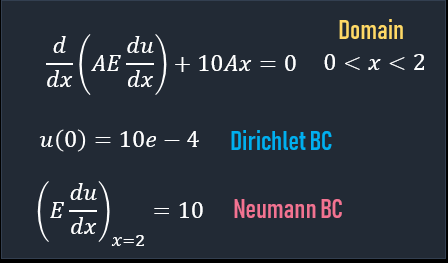

close all;

% Declare symbolic variable

syms As(i0,j0);
syms bs(i0);
syms psi(x,i0)
syms psid(x,i0)
syms A0(x);
syms f(x);

% Define A and E
A0(x)=2;
E=10e5;
L=2;

% Define the function
f(x) = 10*A0*x;
D=10e-4; % Dirichlet BC value
Q=10; % Neumann BC value
syms u(x);

Let us get the exact solution first.


% Exact Solution
ode = diff((A0*E*diff(u,x,1)),x,1) == -f;

Du=E*diff(u,x,1);
cond1 = u(0) == D;
cond2 = Du(L) == Q;
conds = [cond1 cond2];

% Solve ODE symbolically
uSol(x) = dsolve(ode,conds);
stresSol(x) = E*diff(uSol,x);

Now, generate the basis function and its derivative. 

We choose: $\psi_i =x^i$


% Select the dimension
N=4;

psi(x,i0)= (x^i0); % Basis function
psid(x,i0) = (diff(psi,x,1));   % First Derivative

Generate A and b matrix:

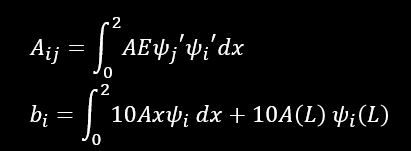

bs(i0) = (int(f*psi(x,i0),x,[0 L])) + 10*A0(L)*psi(L,i0); % Symbloic function for b
As(i0,j0) = int(A0*E*psid(x,i0)*psid(x,j0),x,[0 L]); % Symbolic function for A

A = zeros(N,N);
b = zeros(N,1);
for i1=1:N
    for j1=1:N
        A(i1,j1)=double(As(i1,j1));
    end
    b(i1) = double(bs(i1));
end

Solve for c.

% The coeff matrix for system
c=A\b;


Generate the vector over domain for basis function and its derivative.


divs=100; % Divisions for domain
X = linspace(0,L,divs); % Domain

ps = zeros(divs,N);
psd = zeros(divs,N);
for a=1:N
    ps(:,a) = double(psi(X,a));
    psd(:,a)= double(psid(X,a));
end


Construct the approximate solution for u and u' (stress).


U= D + c'*ps';
stress = E*c'*psd';


Plot the results.

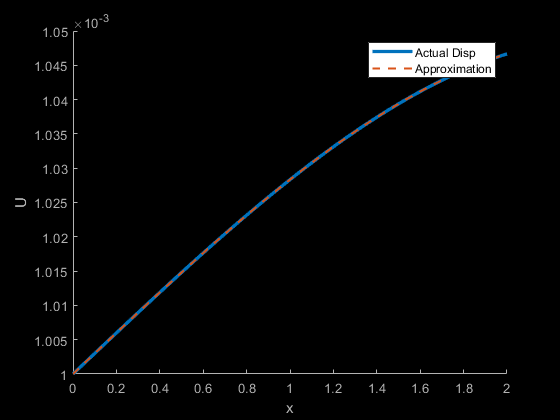


% Ploting Actual Solution and Trial solution
figure(1)
hold on;
plot(X,double(uSol(X)),"Linewidth",2.5)
plot(X,U,'--',"Linewidth",1.5)
legend("Actual Disp","Approximation")
ylabel("U")
xlabel("x")
blackFig;

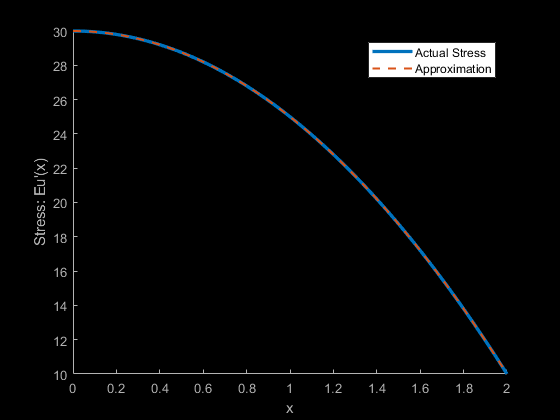


% Plotting Stress
figure(2)
hold on;
plot(X,stresSol(X),"Linewidth",2.5)
plot(X,stress,'--',"Linewidth",1.5)
legend("Actual Stress","Approximation")
ylabel("Stress: Eu'(x)")
xlabel("x")
blackFig;

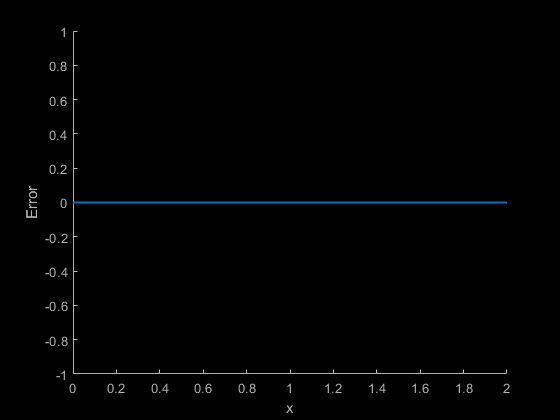


% Plotting Error
figure(3)
hold on;
plot(X,round(double(uSol(X)-U),7),'-',"Linewidth",1.5)
ylabel("Error")
xlabel("x")
blackFig;